%BME3503C Final Project - EKG analysis
%PART 1: IMPORT DATA
data = readtable('ecg.csv');
% each row corresponds to an ecg example
ecg_data = data(:, 1:140);
% compute columns (140)
r = height(ecg_data);
disp(r);

        4998



% compute columns (4998)
c = width(ecg_data);
disp(c);

   140



% PART 2: VISUALIZE DATA
% Plot normal EKG signals on Figure 1
% Assuming ecg_data is a cell array with EKG signals
% Plot normal EKG signals on Figure 1
figure;
hold on;
for i = 1:150
    plot(ecg_data{i, 1:140}, 'black');
end
hold off;
title('Normal ECG Signal');
xlabel('Data Point');
ylabel('Voltage Value');
xlim([0 140]);1

ans = 1

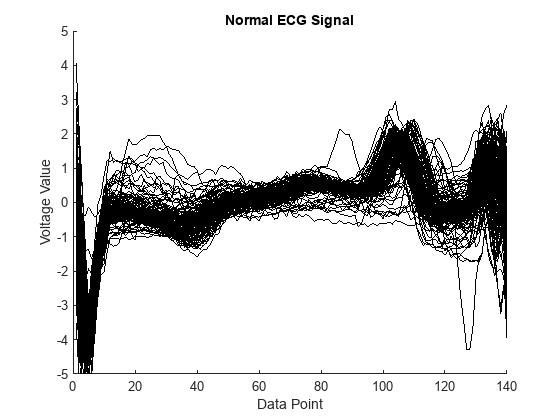

ylim([-5 5]);

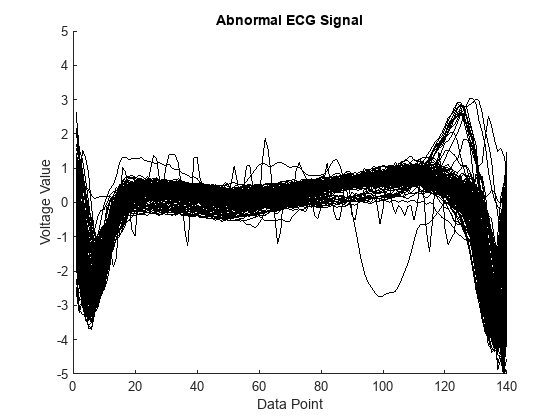

% Plot abnormal EKG signals on Figure 2
figure;
hold on;
for j = 300:450
    plot(ecg_data{j, 1:140}, 'black');
end
hold off;
title('Abnormal ECG Signal');
xlabel('Data Point');
ylabel('Voltage Value');
xlim([0 140]);
ylim([-5 5]);

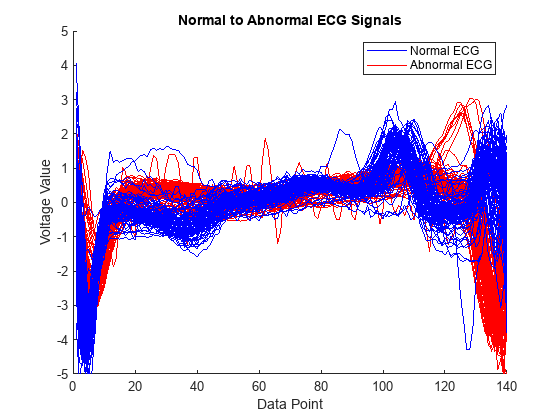

figure;
hold on;
for j = 300:400
    abnormal = plot(ecg_data{j, 1:140}, 'r');
end
hold on;
for i = 1:100
    normal = plot(ecg_data{i, 1:140}, 'b');
end

legend([normal(1), abnormal(1)],'Normal ECG', 'Abnormal ECG');
title('Normal to Abnormal ECG Signals');
xlabel('Data Point');
ylabel('Voltage Value');

xlim([0 140]);
ylim([-5 5]);

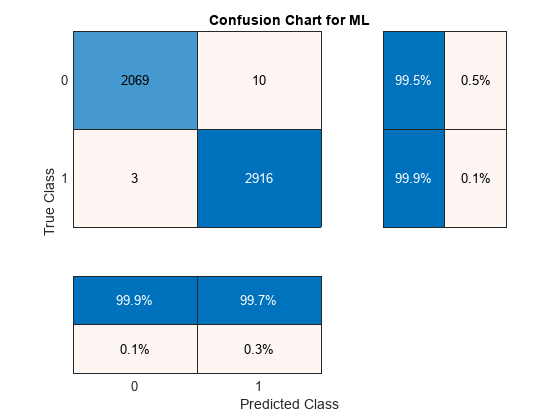

model = trainClassifier(data);
prediction1 = model.predictFcn(data(:,:));
MLAccuracytrain = sum(prediction1 == data.Var141)/numel(prediction1)*100;

figure
confusionchart(data.Var141,prediction1,'ColumnSummary','column-normalized','RowSummary','row-normalized','Title','Confusion Chart for ML');

% Separate data set into a training and testing group
% 80% of dataset goes towards training and 20% towards testing
cv = cvpartition(size(data,1), 'Holdout', 0.2); 
% assign group variables
cv_train = training(cv);
cv_test = test(cv);
trainingData = data(cv_train, :);
testData = data(cv_test, :);
% confirm 80% of the original data in the 'training set'
disp(height(trainingData)); 

        3999



% Confirm 20% of the original data in the 'testing set'
disp(height(testData)); 

   999



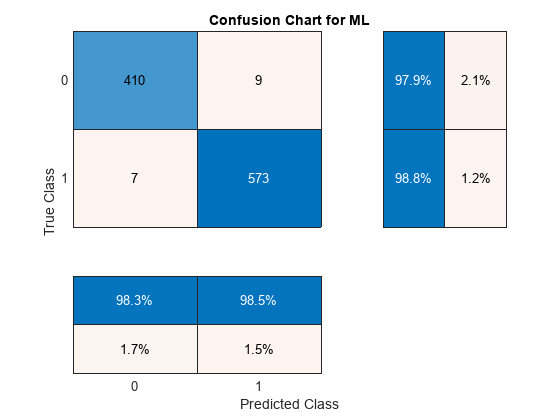

% train the data with the model by calling 'trainClassifier' function
model = trainClassifier(trainingData); 
% predict with the remaining test data
predictions = model.predictFcn(testData(:,:));
% plot confusion matrix and accuracy of the machine learning model
figure;
confusionchart(testData.Var141,predictions,'ColumnSummary','column-normalized', 'RowSummary','row-normalized','Title','Confusion Chart for ML');

% calculate the accuracy of the machine learning model
accuracy = sum(predictions == testData.Var141) / numel(predictions)*100;
disp(['Test Accuracy: ', num2str(accuracy), '%']);

Test Accuracy: 98.3984%
